# Constellation-Constrained Capacity

In this demo, we illustrate how to compute the constellation constrained capacity described in the lecture.   

## Computing the Constellation-Constrained Capacity 

We first compute the constellation-constrained capacity for M-QAM data on an AWGN channel.  

% Number of symbols per trial
nsym = 1000;

% Bits per sym to test
bpsTest = [2,4,6,8];
nmod = length(bpsTest);

% SNRs to test
EsN0Test = linspace(-10,30,41);
nsnr = length(EsN0Test);

% Initialize array
capPerSym = zeros(nsnr,nmod);

for j = 1:nmod
    % Select the modulation order
    bitsPerSym = bpsTest(j);
    M = 2^bitsPerSym;

    % Get the constellation
    ind = (0:M-1)';
    s0 = qammod(ind, M, 'UnitAveragePower', true);

    % Unit variance noise
    w0 = sqrt(1/2)*(randn(nsym,1) + 1i*randn(nsym,1));

    % Generate random symbols
    ind = randi([0,M-1], nsym, 1);
    s = qammod(ind, M, 'UnitAveragePower', true);

    for i = 1:nsnr
                
        % Add noise
        EsN0 = EsN0Test(i);
        wvar = db2pow(-EsN0);
        r = s + sqrt(wvar)*w0;
        
        % Compute posterior probabilities        
        tol = 1e-8;
        D = abs(r - s0.').^2;
        P = exp(-D/wvar) + tol;
        Psum = sum(P,2);
        P = P ./ Psum;
        
        % Compute entropy
        H = -sum(P.*log2(P), 2);
        capPerSym(i,j) = bitsPerSym - mean(H);

    end
end


We now plot the results.

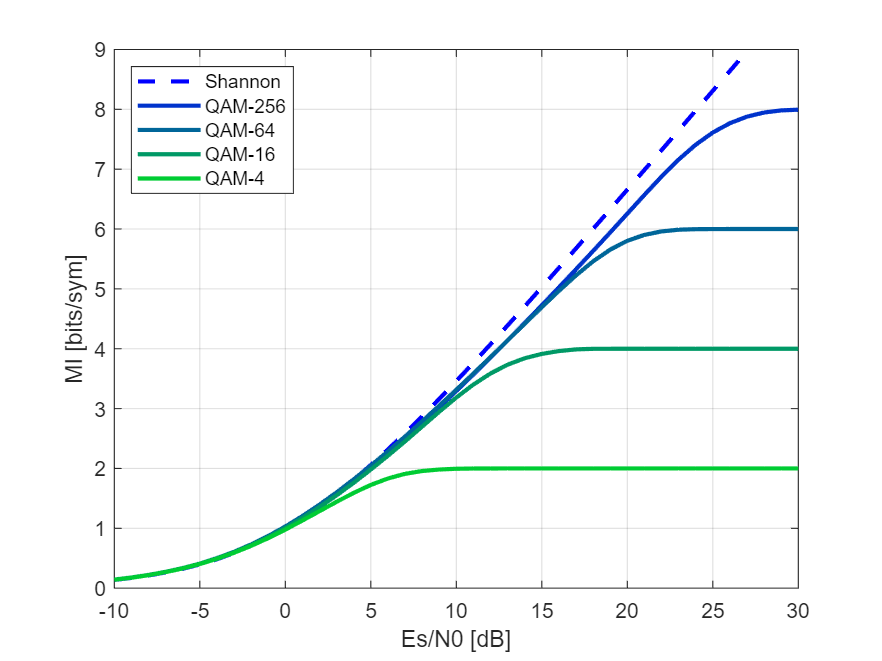

% Compute Shannon capacity
clf;
Copt = log2(1 + db2pow(EsN0Test));
plot(EsN0Test, Copt, '--', 'LineWidth', 2, 'Color', [0 0 1], ...
    'DisplayName', 'Shannon');
hold on;

for i = nmod:-1:1
    t = i/(nmod+1);
    name = sprintf('QAM-%d', 2^bpsTest(i));
    plot(EsN0Test, capPerSym(:,i), 'LineWidth', 2,...
        'Color',[0 1-t t], 'DisplayName', name);
end
hold off;
legend('Location','Northwest');


grid on;
xlabel('Es/N0 [dB]');
ylabel('MI [bits/sym]');
ylim([0,9]);

## Capacity with Bit-Wise LLR

The constellation constrained capacity assumes symbolwise decoding.  In general, symbols are decoded bitwise.  We use the BCE method to estimate the capacity in this case.  We first plot the BCE (binary cross entropy) function:

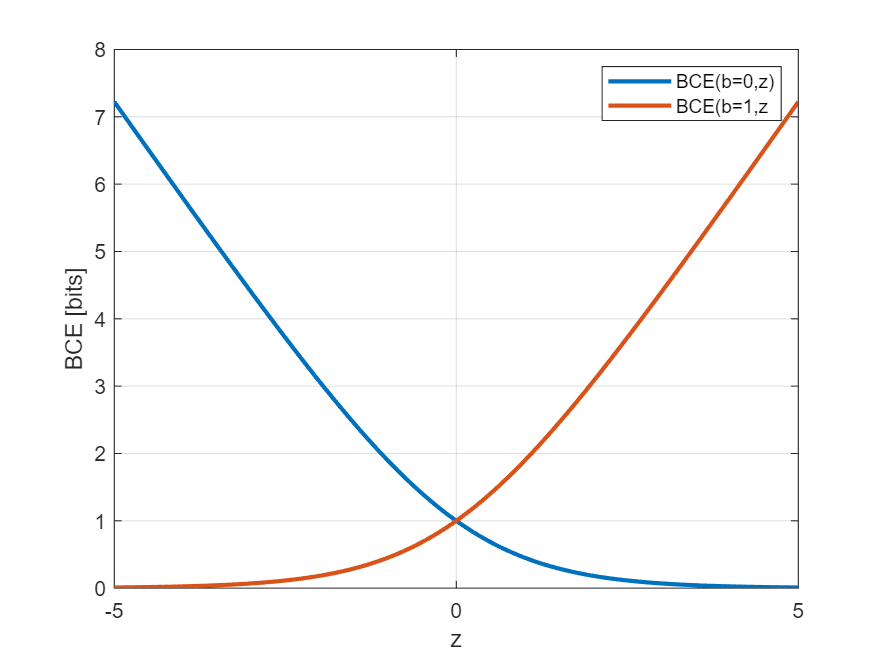

z = linspace(-5,5,100)';
bce0 = (log(1 + exp(z)) - z)/log(2);
bce1 = (log(1 + exp(z)))/log(2);

plot(z, [bce0 bce1], 'LineWidth', 2);
grid on;
legend('BCE(b=0,z)', 'BCE(b=1,z');
xlabel('z');
ylabel('BCE [bits]');

We now compute and plot the capacity with bit-wise LLRs.


% Bits per sym to test
bpsTest = [2,4,6,8];
nmod = length(bpsTest);

% SNRs to test
EsN0Test = linspace(-10,30,41);
nsnr = length(EsN0Test);

capPerSym = zeros(nsnr,nmod);

% Number of symbols per trial
nsym = 1000;

for j = 1:nmod
    bitsPerSym = bpsTest(j);
    M = 2^bitsPerSym;

    % Generate random bits
    nbits = bitsPerSym*nsym;
    b = randi([0,1], nbits, 1);
    s = qammod(b,M,'InputType','bit','UnitAveragePower',true);

    % Unit variance noise
    w0 = sqrt(1/2)*(randn(nsym,1) + 1i*randn(nsym,1));

    for i = 1:nsnr
        EsN0 = EsN0Test(i);
        wvar = db2pow(-EsN0);
        w = sqrt(wvar)*w0;

        r = s + w;
        llr = qamdemod(r,M,'OutputType','approxllr', ...
            'UnitAveragePower',true,'NoiseVariance', wvar);
        llr = -llr;

        % Compute BCE
        %   if llr > 0   log(1+exp(-llr)) + llr*(1-b)
        %   if llr < 0   log(1+exp(llr))  - llr*b
        %   Hence, it is log(1+exp(-abs(llr)) -llr*b + max(llr,0);
        bce = log(1 + exp(-abs(llr))) - llr.*b + max(llr,0);

        % Convert to bits
        bce = bce / log(2);        

        % Capacity
        capPerSym(i,j) = sum(1-bce)/nsym;
    end
end

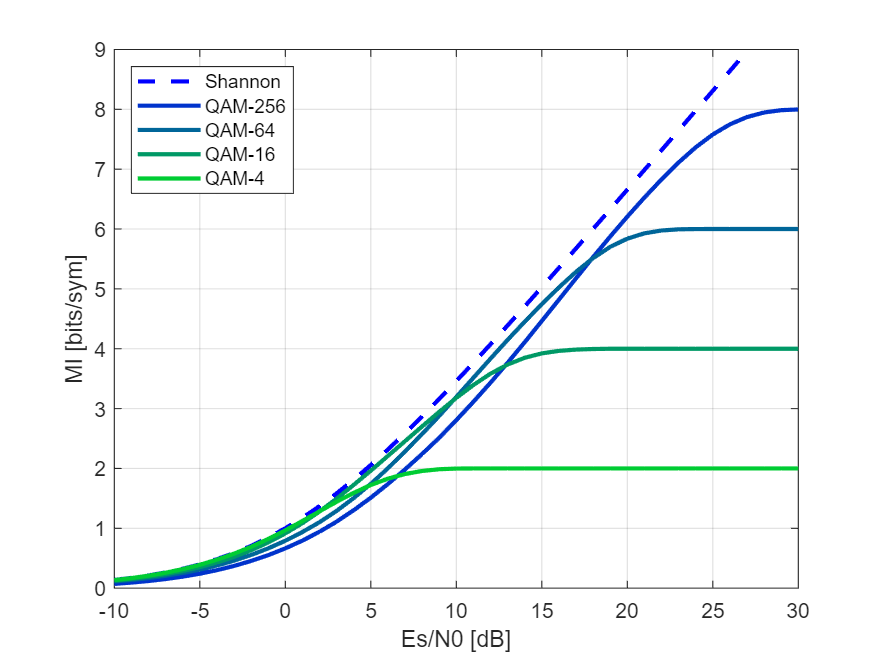



% Compute Shannon capacity
clf;
Copt = log2(1 + db2pow(EsN0Test));
plot(EsN0Test, Copt, '--', 'LineWidth', 2, 'Color', [0 0 1], ...
    'DisplayName', 'Shannon');
hold on;

for i = nmod:-1:1
    t = i/(nmod+1);
    name = sprintf('QAM-%d', 2^bpsTest(i));
    plot(EsN0Test, capPerSym(:,i), 'LineWidth', 2,...
        'Color',[0 1-t t], 'DisplayName', name);
end
hold off;
legend('Location','Northwest');


grid on;
xlabel('Es/N0 [dB]');
ylabel('MI [bits/sym]');
ylim([0,9]);